**Modeling a simple Ideal Organic Rankine Cycle **

There are four main components for ORC:

- Boiler or Evaporator

- Turbine

- Condenser

- Feed Pump

The goal would be to design or model a system with high effeciency. To achieve that we will set temperature and pressure accordingly.

"**XSteam Fluid Library**" has used in this modeling. (It is a free open source fluid property library.)

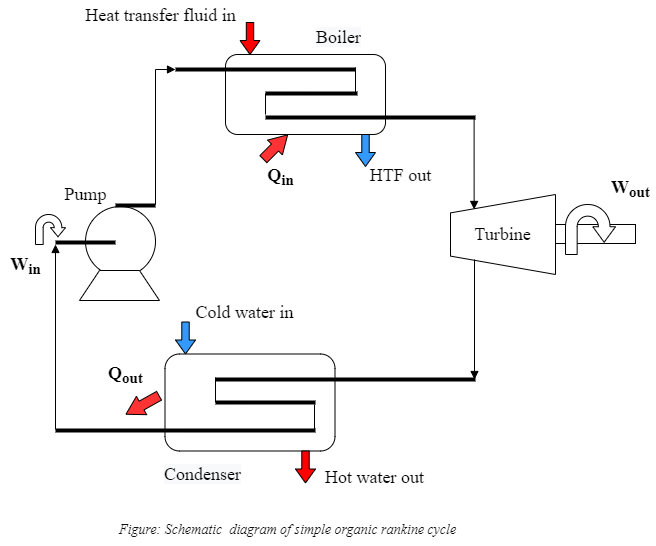

Defining the input parameters

Assuming that the first point is temperature going into the turbine from

the boiler or Evaporator. 

Then,

    the turbine inlet parameters,

Exit temperature from Boiler(T_1) = 450 degree centigrade

Pressure at the first point (P_1) = 30 bar

Pressure at the second point (P_2) = 0.05 bar

Rate of Mass flow (M) = 1.2 kg/s

Efficiency of turbine (T_eff) = 0.95

% Defining turbine inlet variables

T_1 = 450;
P_1 = 30;
P_2 = 0.05;
M = 1.2;
T_eff = 0.95;

Now,

Defining the thermodynamics properties of the fluid at the first point (Boiler);

Enthalpy at the first point (H_1) in J/kg

Entropy at the first Point (S_1) in J/kg/K

Density at the first point (D_1) in kg/m^3

% Defining the thermodynamics properties at Boiler
H_1 = XSteam('h_pT', P_1, T_1)

H_1 = 3.3447e+03

S_1 = XSteam('s_pT', P_1, T_1)

S_1 = 7.0853

D_1 = XSteam('rho_pT', P_1, T_1)

D_1 = 9.2692

Defining the thermodynamics properties of the fluid at the second point (Turbine);

Temperature at the second point(T_2) = 35 degree centigrade

Entropy at the second Point (S_2) = Entropy at the first Point (S_1) J/kg/K

Enthalpy at the second point (H_2) in J/kg

Density at the second point (D_2) in kg/m^3

% Defining the thermodynamics properties of the fluid at Turbine

T_2 = 35; 
S_2 = S_1;
H_2 = XSteam('h_pT', P_2, T_2)

H_2 = 2.5648e+03

D_2 = XSteam('rho_pT', P_2, T_2)

D_2 = 0.0352

Defining the thermodynamics properties of the fluid at the third point (Condenser);

Efficiency of feed pump (P_eff) = 0.9

Temperature at the third point(T_3) = T_2

Entropy at the third Point (S_3)  in J/kg/K

Pressure at the third point (P_3) in Pa

Enthalpy at the third point (H_3) in J/kg

Density at the third point (D_3) in kg/m^3

Specific volume at the third point  (SV_3) = 1/D_3 m^3/kg

% Defining the thermodynamics properties of the fluid at Condenser

P_eff = 0.9;
T_3 = T_2;
P_3 = P_2;
S_3 = XSteam('sL_p', P_3)

S_3 = 0.4763

H_3 = XSteam('hL_p', P_3)

H_3 = 137.7651

D_3 = XSteam('rho_pT', P_3, T_3)

D_3 = 0.0352

SV_3 = 1/D_3

SV_3 = 28.3849

Defining the thermodynamics properties of the fluid at the forth point (Feed pump);

Pressure at the forth point (P_4) =  Pressure at the first point (P_1) 

Pump work (PW) = (SV_3*(P_4 - P_3)) / P_eff

Enthalpy at the forth point (H_4) in J/kg

Entropy at the forth Point (S_4)  in J/kg/K

% Defining the thermodynamics properties of the fluid at Feed pump

P_4 = P_1; 
PW = (SV_3*(P_4 - P_3)) / P_eff

PW = 944.5854

S_4 = S_3;
H_4 = XSteam('h_ps', P_4, S_4)

H_4 = 140.7622

Also,

Specific heat capacity of volume (Cv) in J/kg/K

Specific heat capacity of pressure (Cp) in  J/kg/K

Gamma coeficient (G_c) = Cp / Cv 

Temperature at the forth point (T_4) = T_3*(P_4 / P_3)^((G_c - 1) / (G_c)) Kelvin

% Defining the thermodynamics properties of the fluid at Feed pump outlet

Cv = XSteam('cvL_p',P_3)

Cv = 4.1053

Cp = XSteam('cpL_p',P_3)

Cp = 4.1796

G_c = Cp / Cv

G_c = 1.0181

T_4 = T_3*(P_4/P_3)^((G_c - 1)/(G_c))

T_4 = 39.2143

So, 

Heat input (H_i) = Mass flow (M) * (H_1 - H_4)

Turbine work (TW) = (Mass flow (M) * (H_1 - H_2)) * T_eff J/kg

Shaft output power (SOP) = TW - PW J/kg

Efficiency of cycle (Cyc_eff) = SOP / H_i * 100

Total Net work done (NW) = SOP

Total work ratio (TWR) = Total Net work done / Turbine work

% Calculating the heat input

H_i = M * (H_1 - H_4)

H_i = 3.8447e+03


% Calculating the cycle performance and work done

TW = (M * (H_1 - H_2)) * T_eff

TW = 888.9935

SOP = (TW - PW) * 100

SOP = -5.5592e+03

NW = TW - PW

NW = -55.5919

Cyc_eff = SOP/H_i

Cyc_eff = -1.4459

TWR = NW / TW

TWR = -0.0625

% Variable calculation at the fifth point 

T_5 = XSteam('Tsat_p',P_1)

T_5 = 233.8584

S_5 = XSteam('sL_p',P_1)

S_5 = 2.6456

H_5 = XSteam('hL_p',P_1)

H_5 = 1.0084e+03

% Variable calculation at the sixth point 

T_6 = T_5;
S_6 = XSteam('sv_p',P_1)

S_6 = 6.1858

H_6 = XSteam('hv_p',P_1)

H_6 = 2.8033e+03

Graphic representation of the data

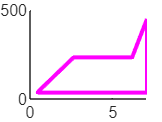


% Temperature vs Entropy plotting

figure(1);

hold on;

plot([S_1, S_2, S_3, S_4, S_5, S_6, S_1],[T_1, T_2, T_3, T_4, T_5, T_6, T_1], ...
    'LineWidth',2, 'Color','m');


sat_curve = linspace(0, T_1, 600); % Saturation of curve
for i = 1:length(sat_curve)
    S_l(i) = XSteam('sL_T', sat_curve(i));
    S_v(i) = XSteam('sv_T', sat_curve(i));
    h_l(i) = XSteam('hL_T', sat_curve(i));
    h_v(i) = XSteam('hv_T', sat_curve(i));
end

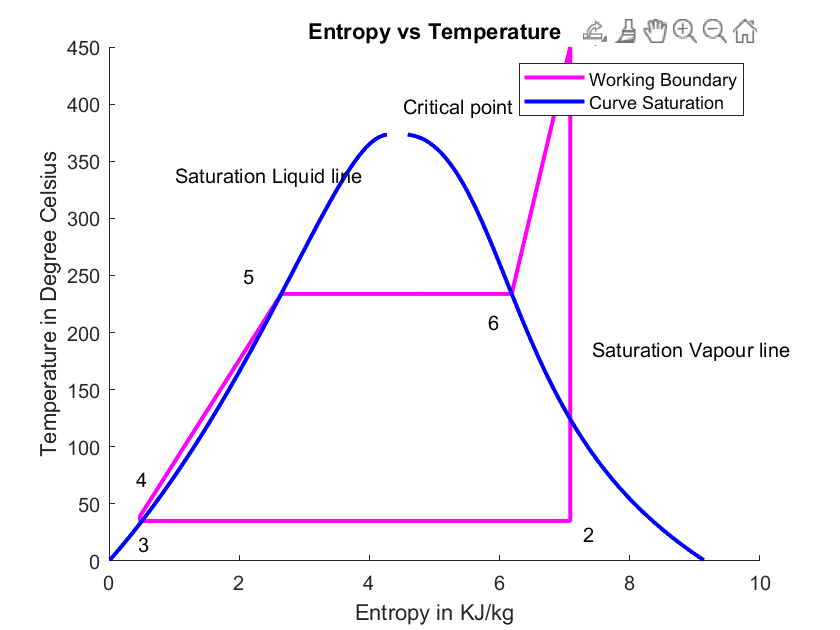

plot(S_l, sat_curve, 'linewidth', 2, 'color', 'b');
plot(S_v, sat_curve, 'linewidth', 2, 'color', 'b');
% Pasting the string with gtext command
gtext('1');
gtext('2');
gtext('3');
gtext('4');
gtext('5');
gtext('6');
gtext('Critical point');
gtext('Saturation Liquid line');
gtext('Saturation Vapour line');
xlabel('Entropy in KJ/kg');
ylabel('Temperature in Degree Celsius');
title('Entropy vs Temperature');
legend('Working Boundary', 'Curve Saturation')


clf

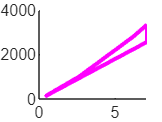


% Plotting the Entropy vs Enthalpy 

figure(2);

hold on;

plot([S_1, S_2, S_3, S_4, S_5, S_6, S_1], [H_1, H_2, H_3, H_4, H_5, H_6, H_1], ...
    'LineWidth',2, 'Color','m');

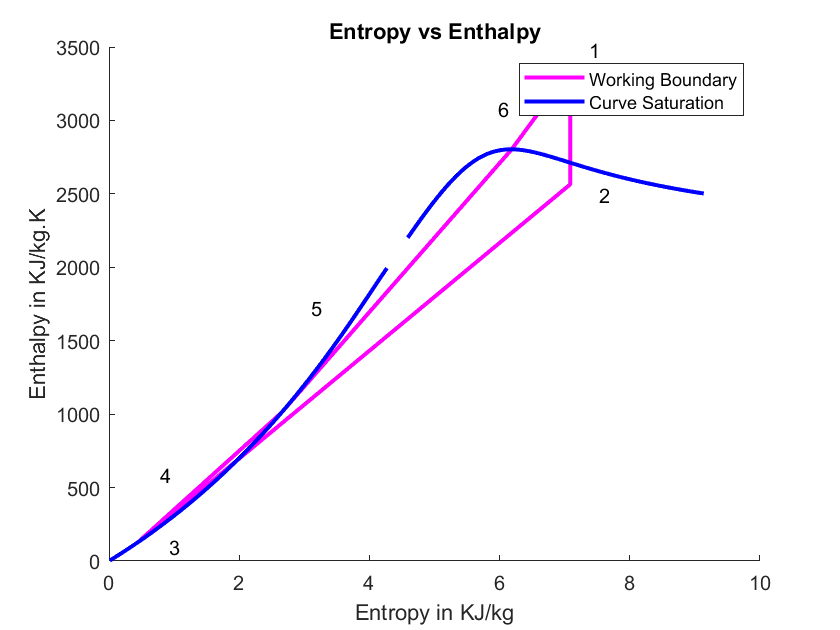


plot(S_l, h_l, 'LineWidth', 2, 'Color', 'b');
plot(S_v, h_v, 'LineWidth', 2, 'Color', 'b');
gtext('1');
gtext('2');
gtext('3');
gtext('4');
gtext('5');
gtext('6');
xlabel('Entropy in KJ/kg');
ylabel('Enthalpy in KJ/kg.K');
title('Entropy vs Enthalpy');
legend('Working Boundary', 'Curve Saturation')